# TPV Over Section 2 of X-43

%% Constants and Variable Initialization

% Table 1 Variable inputs for JP-7 and other constants
k_w = 0.598; % W/(m-K)
nu_w = 1.006e-6; % m^2/s
c_w = 4180; % J/(kg-K)
rho_w = 998; % kg/m^3
k_jp7 = 0.12;
nu_jp7 = 0.725e-6;
c_jp7 = 2300;
rho_jp7 = 780; %kg/m^3
W = 10e-3; % m
L = 10e-3; % m
H_c = 500e-6; % m
dp = 10; % kPa
Qdot = [mean(Qiso(1,2:end-1))/(100^2), mean(Qiso(2,2:end-1))/(100^2)]; % W/cm^2
Tavg = [mean(Tiso(1,2:end-1)), mean(Tiso(2,2:end-1))]; % K
T_f_in = 293; % K
omega_tw_min = 0.1; % twiddle omega
T_max = 325; % K
Ncells = (0.74-0.2) / L;
Pcell = (2.5 / 1680) * Tavg;
Ptot = (2.5 / 1680) * Tavg * Ncells;
pk = [1 -1.3553 1.9467 -1.7012 0.9564 -0.2537];
qk = [8.235 -13.496 16.839 -10.235 1.6157 0.609];
rk = [5.385 -14.37 35.857 -45.236 30.427 -8.4936];


% Run through AoA values and calculate Omega ~ 
for aoa = 1:length(Qdot)
    % omega ~ c values
    for i = 1:30
        if i <= 10
            omega_t_c(i) = 0.01 + (i-1)*0.01;
        elseif i > 10 && i <= 20
            omega_t_c(i) = omega_t_c(i-1) + 0.1;
        else 
            omega_t_c(i) = omega_t_c(i-1) + 1;
        end
    end
    
    for i = 1:30
        omega_t_e = omega_t_c(i) + omega_tw_min;
        x_tilde = 1; % end of channel
    
        if omega_t_c(i) > 0 && omega_t_c(i) < 1
            Po = 0;
            for j = 1:6
                Po = Po + pk(j) * omega_t_c(i)^(j-1);
            end
            Po = 24 * Po;
        else
            Po = 0;
            for j = 1:6
                Po = Po + pk(j) * omega_t_c(i)^(-(j-1));
            end
            Po = 24 * Po;
        end
    
    
        if omega_t_c(i) > 0 && omega_t_c(i) < 1
            Nu = 0;
            for j = 1:6
                Nu = Nu + qk(j) * omega_t_c(i)^(j-1);
            end
        else
            Nu = 0;
            for j = 1:6
                Nu = Nu + qk(j) * omega_t_c(i)^(-(j-1));
            end
        end
        
        m_tilde = 2 * omega_t_c(i)^3 / (Po * (1 + omega_t_c(i))^2);
        
        chi = k_jp7 * nu_jp7 * L^2 / (c_jp7 * 1000 * dp * H_c^4);
    
        theta_f = chi * (omega_t_e / m_tilde) * x_tilde;
        
        R_tilde_cap = theta_f;
        R_tilde_conv = 2 * omega_t_e * omega_t_c(i) / (Nu * (1 + omega_t_c(i))*...
            (2 + omega_t_c(i)));
    
        theta_w = R_tilde_cap + R_tilde_conv;
        m_hat = 1000 * dp * H_c^4 / (nu_jp7 * L);
    
        m_dot_int = m_tilde * m_hat;
        m_dot(aoa,i) = m_dot_int * Ncells / Ptot(aoa);
        
        T_hat = (Qdot(aoa) * H_c * 100^2) / k_jp7;
        
        Theta_f = chi * (omega_t_e / m_tilde) * x_tilde;
        Theta_w = Theta_f + (2 * omega_t_e * omega_t_c(i)) / (Nu * (1 + ...
            omega_t_c(i)) * (2 + omega_t_c(i)));
    
        Tw(aoa,i) = Theta_w * T_hat + T_f_in;
        Tf(aoa,i) = Theta_f * T_hat + T_f_in;
    end
end


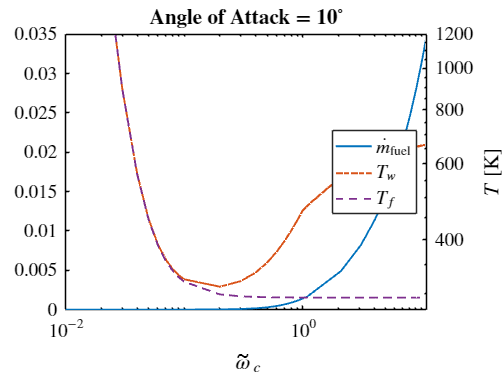

fign = 1;
figure(fign)
yyaxis left
loglog(omega_t_c,m_dot(1,:));

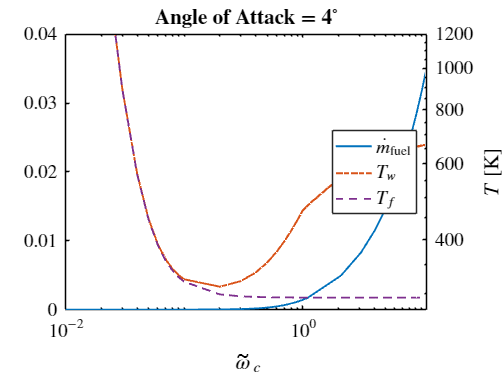

set(gca, 'TickLabelInterpreter','latex','FontSize',16);
yticks(10.^(-8:-1));
ylim([6*10^-9 1.5*10^-1]);
ylabel('$\dot{m}_{\mathrm{fuel}}$ $(\frac{\mathrm{kg}}{\mathrm{s}})/W$','Interpreter','latex');

hold on;
yyaxis right
loglog(omega_t_c,Tw(1,:),'-.');
loglog(omega_t_c,Tf(1,:),'--','Color','#7E2F8E');
yline(T_max,'k:','LineWidth',2);
set(gca, 'YScale', 'log');
ylim([275,1200]);
hold off

ax = gca;
ax.XColor = 'k';
ax.YColor = 'k';
ax.YAxis(1).Color = 'k';
set(gca, 'TickLabelInterpreter','latex','FontSize',16);
title('\textbf{Angle of Attack = 4$^\circ$}','Interpreter','latex');
xlabel('$\widetilde{\omega}_c$');
ylabel('$T$ [K]');
leg = legend('$\dot{m}_{\mathrm{fuel}}$','$T_w$','$T_f$','$T_{max}=325 \; K$',fontsize=16);
set(leg,'interpreter','latex');
set(leg,'location','east');
fign = fign + 1;
figure(fign)
yyaxis left
loglog(omega_t_c,m_dot(2,:));

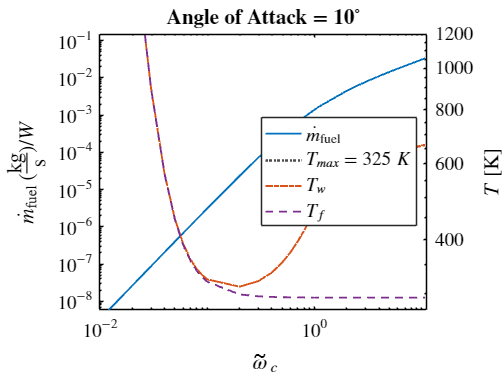

set(gca, 'TickLabelInterpreter','latex','FontSize',16);
yticks(10.^(-8:-1));
ylim([6*10^-9 1.5*10^-1]);
ylabel('$\dot{m}_{\mathrm{fuel}}$ $(\frac{\mathrm{kg}}{\mathrm{s}})/W$','Interpreter','latex');

hold on;
yyaxis right
loglog(omega_t_c,Tw(2,:),'-.');
loglog(omega_t_c,Tf(2,:),'--','Color','#7E2F8E');
yline(T_max,'k:','LineWidth',2);
set(gca, 'YScale', 'log');
ylim([275,1200]);
hold off

ax = gca;
ax.XColor = 'k';
ax.YColor = 'k';
ax.YAxis(1).Color = 'k';
set(gca, 'TickLabelInterpreter','latex','FontSize',16);
title('\textbf{Angle of Attack = 10$^\circ$}','Interpreter','latex');
xlabel('$\widetilde{\omega}_c$');
ylabel('$T$ [K]');
leg = legend('$\dot{m}_{\mathrm{fuel}}$','$T_w$','$T_f$','$T_{max}=325 \; K$',fontsize=16);
set(leg,'interpreter','latex');
set(leg,'location','east');

fign = fign + 1;
min_mdot(1) = m_dot(1,4);
min_mdot(2) = mean([m_dot(2,4),m_dot(2,5)]);
percent_mdot = min_mdot / 0.25 * 100;
disp('TOTAL POWER ESTIMATES:');

TOTAL POWER ESTIMATES:


disp(['  AoA = 4 deg: ',num2str(Ptot(1)),' W/cm^2']);

  AoA = 4 deg: 115.6847 W/cm^2


disp(['  AoA = 10 deg: ',num2str(Ptot(2)),' W/cm^2',newline]);

  AoA = 10 deg: 116.6374 W/cm^2



disp('MINIMUM FLOW RATES NEEDED TO MAINTAIN BELOW 325 K:');

MINIMUM FLOW RATES NEEDED TO MAINTAIN BELOW 325 K:


disp(['  AoA = 4 deg: ',num2str(min_mdot(1)),' kg/s']);

  AoA = 4 deg: 2.0913e-07 kg/s


disp(['  AoA = 10 deg: ',num2str(min_mdot(2)),' kg/s',newline]);

  AoA = 10 deg: 3.0496e-07 kg/s



disp('PERCENTAGE OF MASS FLOW NEEDED FOR TPV:');

PERCENTAGE OF MASS FLOW NEEDED FOR TPV:


disp(['  AoA = 4 deg: ',num2str(percent_mdot(1)),'%']);

  AoA = 4 deg: 8.3653e-05%


disp(['  AoA = 10 deg: ',num2str(percent_mdot(2)),'%']);

  AoA = 10 deg: 0.00012198%
